clear; clc; close all;%
%load('segment.dat'); %
load fisheriris
%X=segment(:,1:19);
X=meas;
C=grp2idx(species);
%C=grp2idx(segment(:,20));

CV_KF5=cvpartition(C,'KFold',5);
fold=1;
trainIdx=CV_KF5.training(fold);
testIdx=CV_KF5.test(fold);
prepro=struct('M',nanmean(X(trainIdx,:)),'S',nanstd(X(trainIdx,:)));
trainX=bsxfun(@rdivide,X(trainIdx,:)-prepro.M,prepro.S);
testX=bsxfun(@rdivide,X(testIdx,:)-prepro.M,prepro.S);
trainLab=C(trainIdx);
testLab=C(testIdx);
%Colours and shapes of markers for plot
obj={'o','s','v','^','d','s','o'};
Grr=[210,210,200]./256;
col= {[100,100,100]./256;[40,120,200]./256;...
    [49,163,100]./256;   [140,81,10]./256;...
    [254,153,41]./256;[186,81,183]./256;...
    [221,28,119]./256};  

If your model can implicitly perform dimensionality reduction to 3 such as the LVQ models reducing rank of relevance matrix to 3, AND

if your models can implicitly compute the prototypes,

then you do not need to compute eigen value decomposition and explicitly project the original data to 3 dimensions as done in this demo. Also if your model makes prototypes by itself then you do not need to compute pseudo-prototypes with class medians.

## EVD and projection of original data to lower dimension (PCA)

dimension=3;
[trainX_EIG,testX_EIG]=toLowerDim(trainX,dimension,testX);

x= projectOnSphere(trainX_EIG);
x_test=projectOnSphere(testX_EIG);
X=-10;Y=80;Z=180;
allData=[x;x_test];

## Training Classifier, Predicting class label with trained classifier, and plotting as a 2 D Mollweide projection

- Choose the classifier you want and train on 'x'

- Classify training data and test data with classifier selected in (1)

- In case of a non prototype based classifier create a pseudo prototype by taking the class-median value using the estimated labels of the training data as classified by the selected classifier

- Convert from cartesian (3D) to spherical ccordinates, and then compute the Mollweide projection. In the sperical projection and its Mollweide transformation in 2D, the separating lines are derived from the model - based on the classification decision boundaries- prototypes or pseudo-prototypes. 

The colour of the data points are according to true labels

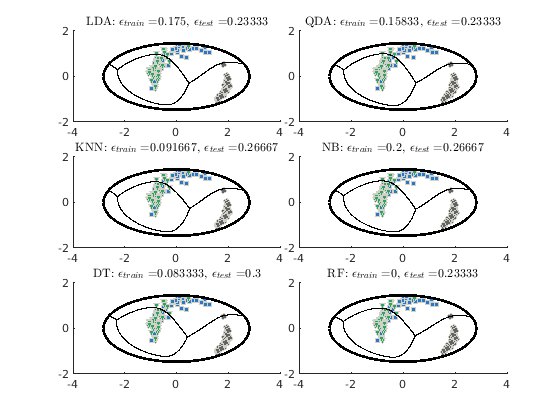

% LDAmodel=fitcdiscr(x,trainLab,'DiscrimType','quadratic');
Classifiers=["LDA","QDA","KNN","NB","DT","RF"];
opt=3; %(option 3=Mollweide)
fig = tiledlayout(numel(Classifiers)/2,2,'TileSpacing','none');
for kdx=1:numel(Classifiers)
    [Model] = ClassifierModel(x,trainLab,Classifiers{kdx});
    estTrain=predict(Model,x);
    estTest=predict(Model,x_test);
    if iscell(estTrain)
        estTrain=str2double(Model.predict(x));
        estTest=str2double(Model.predict(x_test));
    end
    testAcc=sum(estTest==testLab)./length(testLab);
    trainAcc=sum(estTrain==trainLab)./length(trainLab);
    % making pseudo prototype using class medians from training data
    pseudo_prots=cell2mat(arrayfun(@(c) median(x(estTrain==c,:)),unique(C),'uni',0));
    [plotPts]= plotMap2D(pseudo_prots,allData,X,Y,Z,opt);
    intersections = p_intersectingPoints(plotPts.prots3D);
  % connecting the intersection points for plotting the decision
    % boundaries
    curves = p_plotSeparation (intersections, plotPts.prots3D);
    indCls=arrayfun(@(c) find([trainLab; testLab]==c), unique(C),'uni',0);
    nexttile,
    X_r=plotPts.real2D(:,1);
    Y_r=plotPts.real2D(:,2);
    RPoints = zeros(length(trainLab),1);
    for k = 1:length(unique(trainLab)) % loop over each non-empty color group
        indices=indCls{k};
            RPoints(k)=scatter(X_r(indices), Y_r(indices),15,col{k},'filled',...
                'Marker',obj{k},'MarkerEdgeColor',Grr);
        hold on;
        clear indices         
    end  
  %Outline / separation of the different domains
    for idx=1:length(curves)
        v=cell2mat(curves(idx))';
        [azimuth_d,elevation_d,r_d] = cart2sph(v(1,:)',v(2,:)',v(3,:)');
        [X_d,Y_d]=map_projection(opt,azimuth_d, elevation_d,r_d);
        scatter(X_d,Y_d,1,'k.'); hold on;
    end     
 %creating the ellipse for map projection
    [EllipseX,EllipseY]=createEllipse;
    plot(EllipseX,EllipseY,'k-','LineWidth',2);
    title([Classifiers{kdx},'$: \epsilon_{train}=$',num2str(1-trainAcc), ', $\epsilon_{test}=$',num2str(1-testAcc)],'interpreter','latex');
    clear estTrain estTest pseudo_prots X_pp Y_pp Model
   
end

function varargout = toLowerDim(varargin)
    trainData=varargin{1};
    lowDim=varargin{2};
    [vec, vals]=eig(nancov(trainData)); 
    vals=diag(vals);
    [~,ind]=sort(vals,'descend');
    varargout{1}=trainData*vec(ind(1:lowDim),:)';
    if nargin>2
        testData=varargin{3};
        varargout{2}=testData*vec(ind(1:lowDim),:)';
    end
end

function Model = ClassifierModel(varargin)
   trainData=varargin{1};
   trainLab=varargin{2};
   Classifier=varargin{3};
    if strcmp(Classifier,"QDA")==1
        Model=fitcdiscr(trainData,trainLab,'DiscrimType','quadratic');
    elseif strcmp(Classifier,"LDA")==1
        Model=fitcdiscr(trainData,trainLab,'DiscrimType','linear');
    elseif strcmp(Classifier,"NB")==1
        Model=fitcnb(trainData,trainLab);
    elseif strcmp(Classifier,"DT")==1
        Model=fitctree(trainData,trainLab);
    elseif strcmp(Classifier,"RF")==1
        numTrees=50;
        Model=TreeBagger(numTrees,trainData,trainLab,'Method','classification');
    elseif strcmp(Classifier,"KNN")==1
        neighbours=3;
        Model=fitcknn(trainData,trainLab,'NumNeighbors',neighbours);
    end
end